# **DEMO:    **7-dof car,  Design an **Active Suspension **Control Law

## Learning Objectives:

- Apply Newton's 2nd Law and derive the Transverse Vibration Equations of Motion for a 7-dof car model.

- Design a **Linear Quadratic Regulator** to control an Active Suspension system

`Bradley Horton : 17-Sep-2021, bhorton@mathworks.com`

## Background:

Consider the system shown below - a **7 degree of freedom**(dof) model of a car. The model is focused on representing the TRANSVERSE vibrations of the Car Body and the 4 wheel+suspension assemblies.

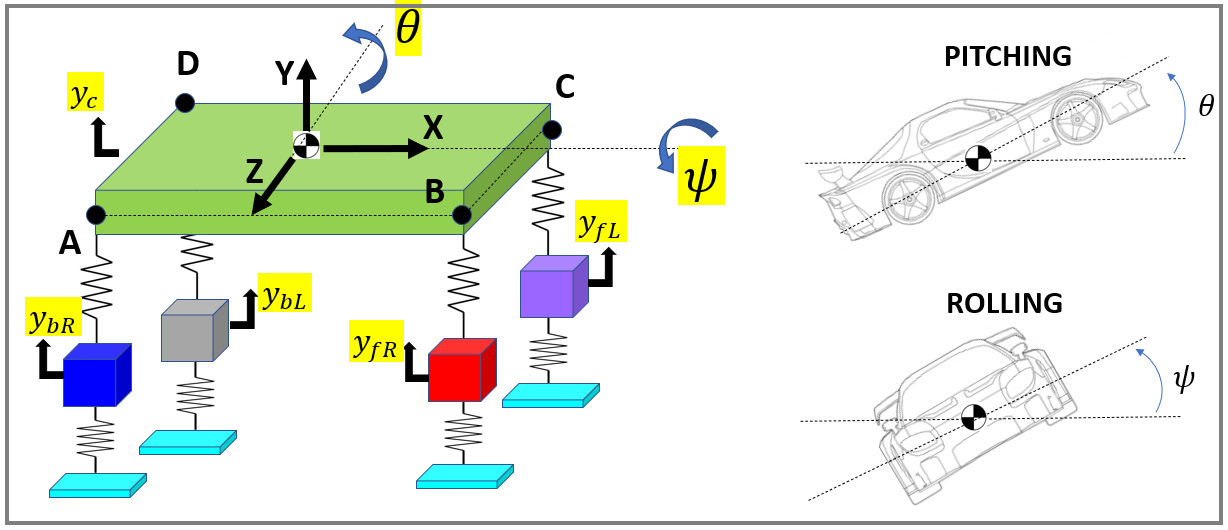

The **7 degree of freedom** of the model are:

-   $y_c$     :    Vertical displacement of car body Center of Mass

-   $\theta$      :    Pitching angular diplacement of the car body

-   $\psi$      :   Rolling angular diplacement of the car body

-   $y_{\textrm{bR}}$    :   Vertical displacement of the **back** RIGHT wheel+suspension assembly

-   $y_{\textrm{fR}}$     :   Vertical displacement of the *front* RIGHT wheel+suspension assembly

-   $y_{\textrm{bL}}$    :    Vertical displacement of the **back** LEFT wheel+suspension assembly

-   $y_{\textrm{fL}}$     :    Vertical displacement of the *front* LEFT wheel+suspension assembly

**NOTE:  **

- All of the Vertical displacements are measured from points corresponding to the car's "equilibrium" position

- In the diagram shown above each spring represents a stiffness and damping element connected in parallel

## Equation of motion derivation:

### Assumptions about the system:

To derive the TRANSVERSE equations of motion of the car system, we'll make the following assumptions about the system:

- **Small angles:   **We'll assume that the angular dof are small, such that $\sin \left(\theta \right)\approx \theta$ and $\sin \left(\psi \right)\approx \psi$

- We'll assume that a BODY fixed frame attached to the Car's Center of Mass(CoM) is alligned with the Principal axes of the body (ie: $\left.I_{\textrm{XY}} =I_{\textrm{XZ}} =I_{\textrm{YZ}} =0\right)$

- The angular velocity of the Car Body is $\omega =\left\lbrack \omega_X \;\;,\omega_Y \;\;,\omega_Z \right\rbrack =\left\lbrack \dot{\psi} \;\;,\;0\;\;,\;\dot{\theta} \right\rbrack$. **   NOTE: **  $\omega_Y ={\dot{\omega} }_Y \;=\;0$

Assumptions $1\to 3$ then allow us to simplify the generic Moment equation for a Rigid body to:

- 
$$\;M^B =I_G^B \;\ldotp {\dot{\omega} }_G^B \;\;\;+\;\;\omega \times \left(I_G^B \ldotp \omega_G^B \right)\;\;\;\Longrightarrow \;\;\;\;M^B =I_G^B \;\ldotp {\dot{\omega} }_G^B \;\;\;\;\Longrightarrow \;\;{\left\lbrack \begin{array}{c}
M_X \\
M_Z 
\end{array}\right\rbrack }^B \;\;=\;\;\left\lbrack \begin{array}{cc}
I_X  & 0\\
0 & I_Z 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\ddot{\psi} \\
\ddot{\theta} 
\end{array}\right\rbrack$$


- see the file [`bh_7dof_CONCEPT_small_angles.mlx`](matlab:  edit bh_7dof_CONCEPT_small_angles.mlx)  for detailed summary on this

OK, so let's start by computing the forces acting on the Car body And the Wheel/suspension assemblies.  

- Assume all dof are moving in their positive direction

- Assume all springs are in Tension

The following diagram shows the car system in this general pose:

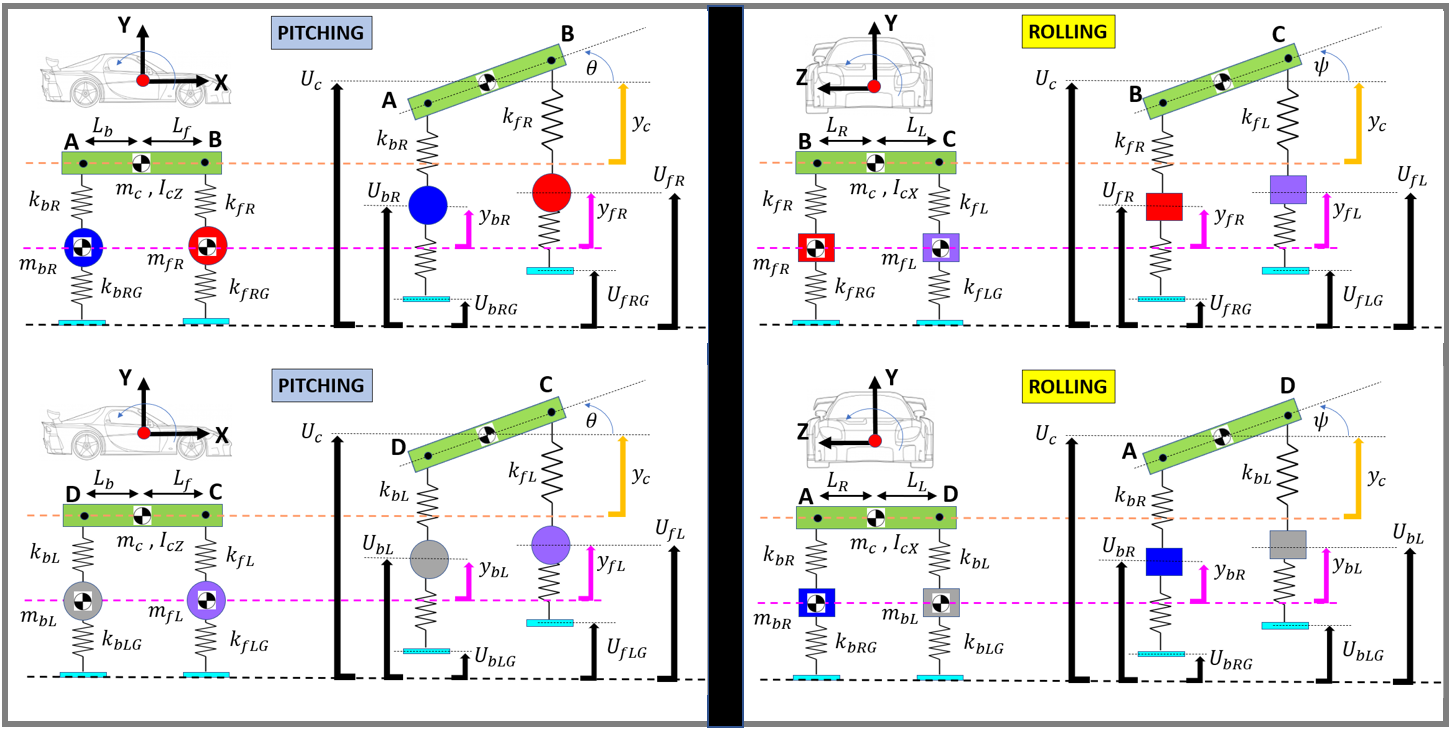

We'll use symbolic variable that match the diagram above:

syms L_b  L_f    L_R   L_L
syms  m_c    I_cZ    I_cX
syms  m_bR   m_fR    m_bL    m_fL
syms  k_bR   k_fR    k_bL    k_fL
syms  c_bR   c_fR    c_bL    c_fL
syms  k_bRG  k_fRG   k_bLG   k_fLG
syms  c_bRG  c_fRG   c_bLG   c_fLG

syms  y_c y_dot_c y_ddot_c
syms  y_dot_bR   y_dot_fR    y_dot_bL   y_dot_fL 
syms  y_ddot_bR  y_ddot_fR   y_ddot_bL  y_ddot_fL
syms  y_bR   y_fR    y_bL    y_fL   

syms  U_bRG  U_fRG   U_bLG   U_fLG  U_dot_bRG  U_dot_fRG   U_dot_bLG   U_dot_fLG

syms theta  theta_dot  theta_ddot
syms   psi    psi_dot    psi_ddot  

## Free Body Diagrams (Conventional suspension):

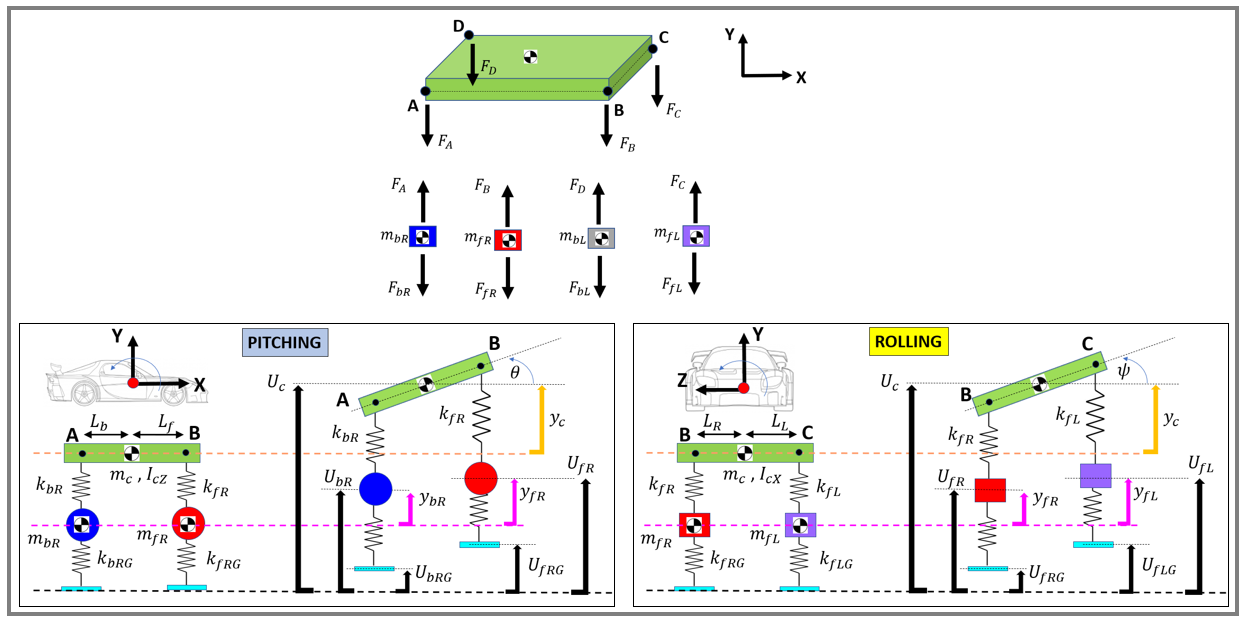

We'll define the forces shown in the above free body diagram 

F_A =   k_bR*(y_c - y_bR - L_b*theta - L_R*psi)   +   c_bR*(y_dot_c - y_dot_bR - L_b*theta_dot - L_R*psi_dot);
F_D =   k_bL*(y_c - y_bL - L_b*theta + L_L*psi)   +   c_bL*(y_dot_c - y_dot_bL - L_b*theta_dot + L_L*psi_dot);
F_B =   k_fR*(y_c - y_fR + L_f*theta - L_R*psi)   +   c_fR*(y_dot_c - y_dot_fR + L_f*theta_dot - L_R*psi_dot);
F_C =   k_fL*(y_c - y_fL + L_f*theta + L_L*psi)   +   c_fL*(y_dot_c - y_dot_fL + L_f*theta_dot + L_L*psi_dot);

Also define the TYRE spring forces $\left(F_{\textrm{bR}} \;\;\;,\;F_{\textrm{fR}} \;\;\;,\;F_{\textrm{bL}} \;\;\;,\;F_{\textrm{fL}} \right)$ acting on each Wheel/suspension assembly:

F_BLUE_bR   = k_bRG*(y_bR - U_bRG) + c_bRG*(y_dot_bR - U_dot_bRG);
F_RED_fR    = k_fRG*(y_fR - U_fRG) + c_fRG*(y_dot_fR - U_dot_fRG);
F_GREY_bL   = k_bLG*(y_bL - U_bLG) + c_bLG*(y_dot_bL - U_dot_bLG);
F_PURPLE_fL = k_fLG*(y_fL - U_fLG) + c_fLG*(y_dot_fL - U_dot_fLG);

## Free Body Diagrams (Active suspension):

The Active suspension system applies additional forces to the car body and corresponding opposite forces to the wheel/suspension assemblies

syms  F_bRe   F_fRe    F_bLe   F_fLe

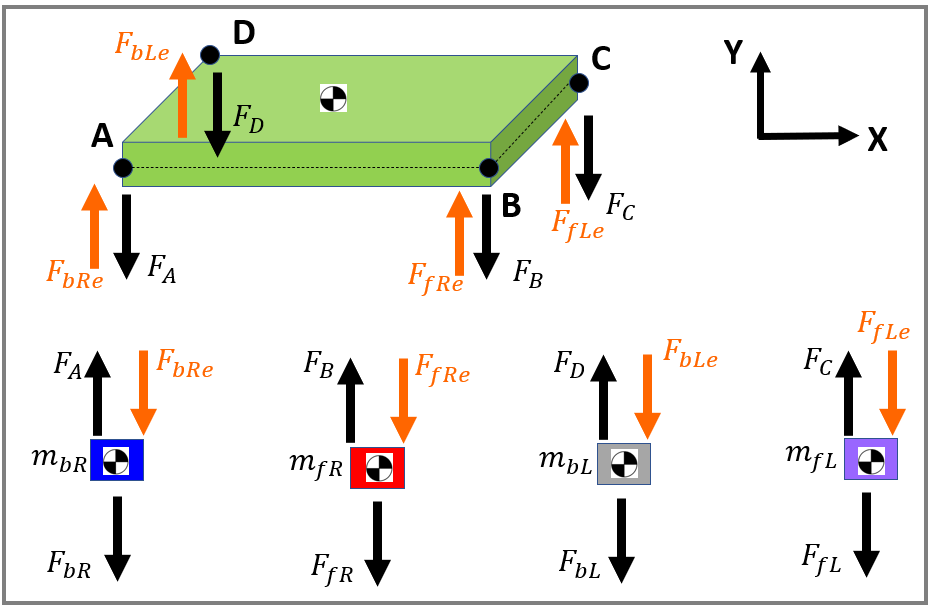

## 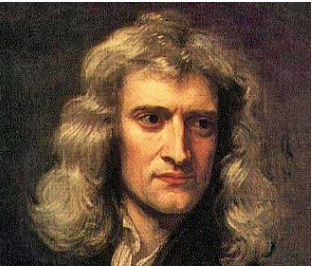  Apply Newton's 2nd Law

From our Free Body diagrams we can now apply Newton's 2nd Law, ie:

-    $m\ldotp \ddot{y} \;=\;\sum_i F_i$    and     $I\ldotp \ddot{\theta} \;=\sum_i \tau_i \;\;$

Consider the **FORCE** equation for each **Wheel/suspension assembly**:

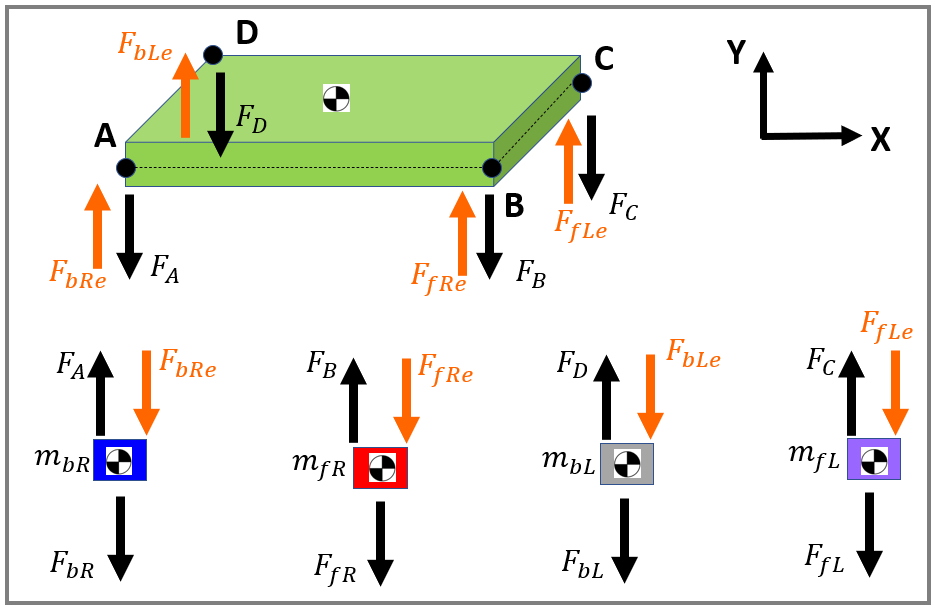

EQ_BLUE_mbR   = m_bR * y_ddot_bR ==  -1*F_BLUE_bR   + F_A   - F_bRe;
EQ_RED_mfR    = m_fR * y_ddot_fR ==  -1*F_RED_fR    + F_B   - F_fRe;
EQ_GREY_mbL   = m_bL * y_ddot_bL ==  -1*F_GREY_bL   + F_D   - F_bLe;
EQ_PURPLE_mfL = m_fL * y_ddot_fL ==  -1*F_PURPLE_fL + F_C   - F_fLe;

Consider the **FORCE** equation for the **GREEN Car Body**:

EQ_GREEN_mc   = m_c  * y_ddot_c  == -1*( F_A  +  F_B  +  F_C  +  F_D )   +   (F_bRe  +  F_fRe  +  F_bLe  +  F_fLe);

Now consider the pitch and roll **MOMENT** equations for the **GREEN Car body:**

-  **RECALL** our small angle assumptions, eg:   [`bh_7dof_CONCEPT_small_angles.mlx`](matlab:  edit bh_7dof_CONCEPT_small_angles.mlx) 

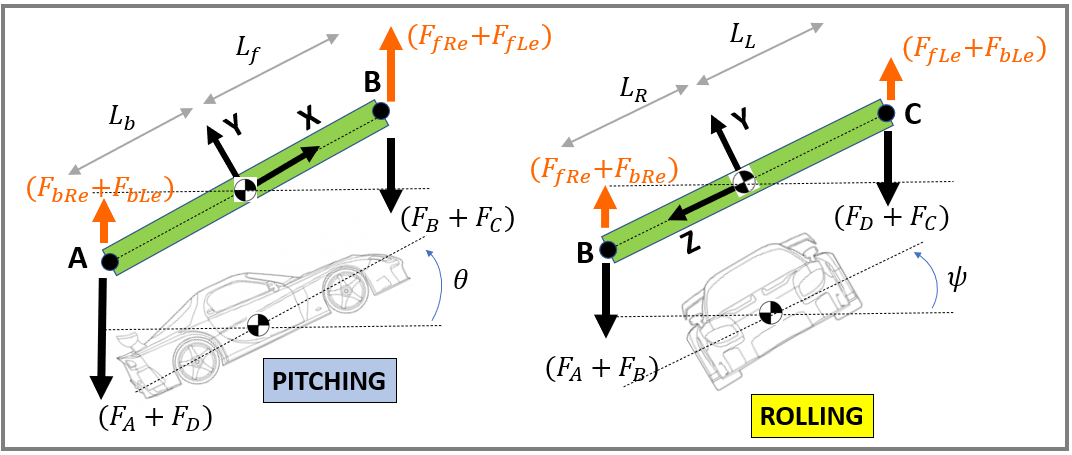

The **PITCH** moment equation for the GREEN Car Body:

EQ_GREEN_IcZ  = I_cZ * theta_ddot ==    (F_A + F_D)*L_b   -  (F_bRe + F_bLe)*L_b       ...
                                      - (F_B + F_C)*L_f   +  (F_fRe + F_fLe)*L_f;

The **ROLL** moment equation for the GREEN Car Body:

EQ_GREEN_IcX  = I_cX * psi_ddot   ==   (F_B + F_A)*L_R   -  (F_fRe + F_bRe)*L_R ...
                                     - (F_C + F_D)*L_L   +  (F_fLe + F_bLe)*L_L;

### Summary:

The 7 equations of motion look like this:

:  Our Small angle assumption results in Linear ODEs ..... which means we can write them in the familiar form $M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;F$ 

my_sys_EQ = [ EQ_GREEN_mc   ;
              EQ_GREEN_IcZ  ;
              EQ_GREEN_IcX  ;     
              EQ_BLUE_mbR   ;
              EQ_RED_mfR    ;
              EQ_GREY_mbL   ;
              EQ_PURPLE_mfL ;  ]

Also, recall our 7 degrees of freedom.  We'll define them in this order 

-  
$$X^T =\left\lbrack \begin{array}{ccccccc}
y_c  & \theta  & \psi  & y_{\textrm{bR}}  & y_{\textrm{fR}}  & y_{\textrm{bL}}  & y_{\textrm{fL}} 
\end{array}\right\rbrack$$


my_7dof_sym_list = [y_c,  theta,  psi,    y_bR,  y_fR,  y_bL,  y_fL]

my_7dof_str_list = string(my_7dof_sym_list);

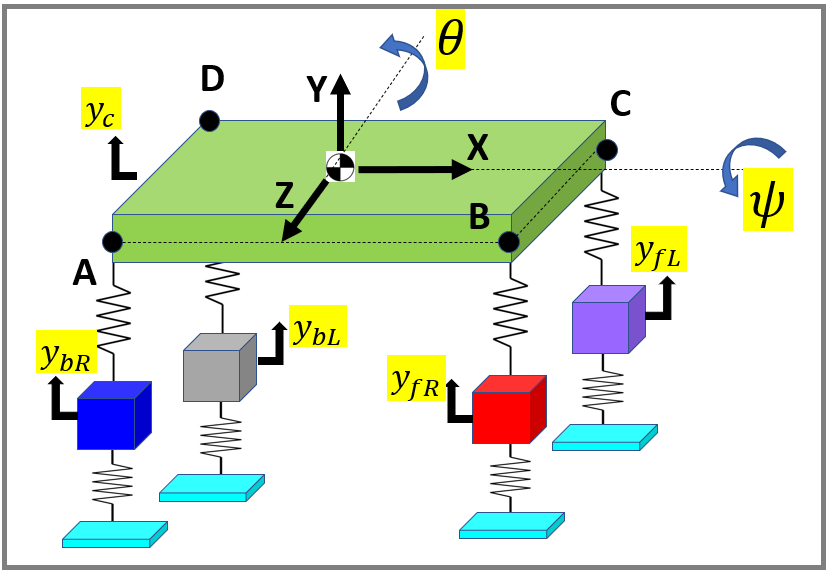

### Now collect equations and extract $M,C,K,F$:

We know that our system equations of motion can be written in the form:

- $M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;F$     where   $X\in R^{\;7\times 1}$     and       $X^T =\left\lbrack \begin{array}{ccccccc}
y_c  & \theta  & \psi  & y_{\textrm{bR}}  & y_{\textrm{fR}}  & y_{\textrm{bL}}  & y_{\textrm{fL}} 
\end{array}\right\rbrack$

We can rewrite this equation as a "mega" equation of the form:

- $\left\lbrack \begin{array}{ccc}
M & C & K
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\ddot{X} \\
\dot{X} \\
X
\end{array}\right\rbrack =\;F$     $\Longrightarrow$     $A\;\ldotp Z=b$      where   $Z\in R^{\;21\times 1}$   and   $A\;=\left\lbrack M\;\;C\;\;K\right\rbrack \;\in R^{\;7\times 21}$

The [`equationsToMatrix()`](matlab:  web(fullfile(docroot, 'symbolic/sym.equationstomatrix.html'))) function will rearrange our 7 equations of motion into this $A\;\ldotp Z=b$  form:

my_Z_vars = [ y_ddot_c,  theta_ddot,  psi_ddot,  y_ddot_bR,  y_ddot_fR,  y_ddot_bL,  y_ddot_fL, ...
               y_dot_c,  theta_dot,   psi_dot,    y_dot_bR,   y_dot_fR,   y_dot_bL,   y_dot_fL, ...
                   y_c,  theta,       psi,            y_bR,       y_fR,       y_bL,       y_fL  ];   
    
[A, b]    = equationsToMatrix(my_sys_EQ, my_Z_vars)    

Great, so now we can finally "extract" our classic $M,C,K,F$ matrices:

M_mat = A(:,  1:7)
C_mat = A(:,  8:14)
K_mat = A(:, 15:21)
F_col = b

## Convert to Simulink blocks

Let's convert our $M,C,K,F$ matrices into Simulink blocks.

-  **NOTE: ** We'll discuss these further in the section called **Next Steps**.

tf_i_should_create_SL_blocks = true;

if(tf_i_should_create_SL_blocks)
    LOC_create_SL_blocks(M_mat, C_mat, K_mat, F_col)
end     

## Preparing for our controller design:

Our mechanical system equations of motion have the form:

- $M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;F$     where   $X\in R^{\;7\times 1}$     and       $X^T =\left\lbrack \begin{array}{ccccccc}
y_c  & \theta  & \psi  & y_{\mathrm{bR}}  & y_{\mathrm{fR}}  & y_{\mathrm{bL}}  & y_{\mathrm{fL}} 
\end{array}\right\rbrack$

What I would like to do next, is **partiton the Force vector** $F$into it's **Road disturbance** forces(eg:  $U_{\textrm{bRG}} \ldotp k_{\textrm{brG}}$, etc )  and it's** Active suspension** forces (eg:  $F_{\mathrm{fLe}}$, etc)

- 
$$M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;F_{\mathrm{ACTIVE}} \;\;+\;F_{\mathrm{ROAD}}$$


The **Active suspension** forces can also be written by extracting the control forces (eg:  $F_{\textrm{fLe}}$, etc) and writing out a matrix expression  $F_{\mathrm{ACTIVE}} =B_F \ldotp u$

- $M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;\;B_F \ldotp u\;\;+\;F_{\mathrm{ROAD}}$       where       $u\;\;=\;{\left\lbrack \begin{array}{cccc}
F_{\mathrm{bRe}}  & F_{\mathrm{fRe}}  & F_{\mathrm{bLe}}  & F_{\mathrm{fLe}} 
\end{array}\right\rbrack }^T$  

So let's **partiton the Force vector **into these components.  First, recall our Force vector $F$: 

F_col

Our Force vector $F$ is made up of our **Road disturbance** forces(eg:  $U_{\textrm{bRG}} \ldotp k_{\textrm{brG}}$, etc )  and our** Active suspension** forces (eg:  $F_{\textrm{fLe}}$, etc)

- 
$$F=F_{\mathrm{ROAD}} \;\;+F_{\mathrm{ACTIVE}}$$


F_active = F_col;
F_active = subs(F_active, [k_bRG,k_fRG,k_bLG,k_fLG, ...
                           c_bRG,c_fRG,c_bLG,c_fLG], zeros(1,8)   );
F_road   = F_col - F_active;

[F_road,   F_active]

Our active suspension forces can be represented as:

- $F_{\textrm{ACTIVE}} \;\;=B_F \ldotp u$      where    $u\;\;=\;{\left\lbrack \begin{array}{cccc}
F_{\textrm{bRe}}  & F_{\textrm{fRe}}  & F_{\textrm{bLe}}  & F_{\textrm{fLe}} 
\end{array}\right\rbrack }^T$

[B_f, ~] = equationsToMatrix(F_active, [F_bRe, F_fRe, F_bLe, F_fLe])

## Design a Controller for our active suspension system

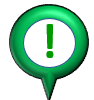**Our Design Goal:**

- Design a Controller that computes the Forces $u\;\;=\;{\left\lbrack \begin{array}{cccc}
F_{\textrm{bRe}}  & F_{\textrm{fRe}}  & F_{\textrm{bLe}}  & F_{\textrm{fLe}} 
\end{array}\right\rbrack }^T$, such that the Car chasis dof  $\left(y_c \;,\theta ,\psi \right)$ are driven to ZERO when subjected to Road disturbances

First we need some NUMERIC values for our car's parameters(ie: mass, damping, stiffness).

- These numeric parameters are in an EXCEL file [`bh_7dof_car_database.xlsx`](matlab:  winopen( "bh_7dof_car_database.xlsx"))

OBJ_car_params =  bh_7dof_car_database_CLS("bh_7dof_car_database.xlsx","PARAMS_SET_LRIDER", "IC_SET_LRIDER");
OBJ_car_params.car_tab

Let's now populate our system $M,C,K$matrices

- This is done in a subfunction `LOC_get_MCK` at the bottom of this script 

[M_num, C_num, K_num ] = LOC_get_MCK(M_mat, C_mat, K_mat, OBJ_car_params);

And the Numeric version of $B_F$ is:

Bf_num = subs(B_f, [L_b,L_f,L_L,L_R], [OBJ_car_params.L_b, OBJ_car_params.L_f, OBJ_car_params.L_L,OBJ_car_params.L_R] );
Bf_num = double(Bf_num);

whos  M_num  C_num  K_num    Bf_num

### Convert 2nd order Mechanical system into First order system:

In preparation for using **State Space** control design techniques, let's "reformat" our Mechanical system equations of motion into a **State Space** form.

Recall that our classic N-dof spring mass damper system is expressed as:

- 
$$M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;\;B_F \ldotp u\;\;+\;F_{\mathrm{ROAD}}$$
        

where      

-  $X^T =\left\lbrack \begin{array}{ccccccc}
y_c  & \theta  & \psi  & y_{\textrm{bR}}  & y_{\textrm{fR}}  & y_{\textrm{bL}}  & y_{\textrm{fL}} 
\end{array}\right\rbrack$   and  

-  
$$u\;\;=\;{\left\lbrack \begin{array}{cccc}
F_{\textrm{bRe}}  & F_{\textrm{fRe}}  & F_{\textrm{bLe}}  & F_{\textrm{fLe}} 
\end{array}\right\rbrack }^T$$


This $2^{\textrm{nd}}$ order system can also be expressed as the $1^{\textrm{st}}$ order **State Space** system :

- 
$$\left\lbrack \begin{array}{c}
\ddot{X} \\
\dot{X} 
\end{array}\right\rbrack \;\;=\;\;\;\left\lbrack \begin{array}{cc}
-M^{-1} \ldotp C & -M^{-1} \ldotp K\\
I_{N\times N}  & 0_{N\times N} 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\dot{X} \\
X
\end{array}\right\rbrack \;\;+\;\;\left\lbrack \begin{array}{c}
M^{-1} \ldotp B_F \\
0_{N\times 4} 
\end{array}\right\rbrack \ldotp u\;\;\;+\;\;\;\left\lbrack \begin{array}{c}
M^{-1} \\
0_{N\times N} 
\end{array}\right\rbrack \ldotp F_{\textrm{ROAD}}$$


which has the form:

- 
$$\begin{array}{l}
\dot{Z} \;=\;A\ldotp Z\;\;+\;B\ldotp u\;\;+\;\;\textrm{disturbance}\\
y\;\;=\;C\ldotp Z\;\;+\;D\ldotp u\;
\end{array}$$
        

- where  $Z=\left\lbrack \begin{array}{c}
\dot{X} \\
X
\end{array}\right\rbrack \in R^{N_z \times 1}$   ,    $u\;\in R^{N_u \times 1}$,    $C\in R^{N_y \times N_z }$  , $D\in R^{N_y \times N_u }$  

And we'll assume the measurables are:

-     
$$y={\left\lbrack \begin{array}{cccccc}
y_c  & \theta  & \psi  & \dot{y_c }  & \dot{\theta}  & \dot{\psi} 
\end{array}\right\rbrack }^T$$


  **ATTENTION: **Note,we going to ***ignore the road displacement forces*** and assume that they are "**disturbances**". When we finally simulate our design we'll see how well our controller can ***reject these diturbances***. So if we ignore the road disturbance forces, our State Space equations become

- $\begin{array}{l}
\dot{Z} \;=\;A\ldotp Z\;\;+\;B\ldotp u\;\;\\
y\;\;=\;C\ldotp Z\;\;+\;D\ldotp u\;
\end{array}$        where  $Z=\left\lbrack \begin{array}{c}
\dot{X} \\
X
\end{array}\right\rbrack \in R^{N_z \times 1}$   ,    $u\;\in R^{N_u \times 1}$,    $C\in R^{N_y \times N_z }$  , $D\in R^{N_y \times N_u }$

sz_T.N  =   size(M_num,1);
sz_T.Nz = 2*size(M_num,1);
sz_T.Nu =   4;
sz_T.Ny =   6;
% 
tmp_A   = [ -inv(M_num)*C_num,   -inv(M_num)*K_num;
                  eye(sz_T.N),   zeros(sz_T.N)       ];

tmp_B   = [  inv(M_num)*Bf_num; 
             zeros(sz_T.N, sz_T.Nu)  ];

tmp_D   = zeros(sz_T.Ny, sz_T.Nu);

tmp_C   = zeros(sz_T.Ny, sz_T.Nz);

Now remember that:

- $y={\left\lbrack \begin{array}{cccccc}
y_c  & \theta  & \psi  & \dot{y_c }  & \dot{\theta}  & \dot{\psi} 
\end{array}\right\rbrack }^T$    and   $Z={\left\lbrack \dot{y_c } \;\;,\;\dot{\theta} \;\;,\dot{\;\;\psi } \;\;,{\dot{y} }_{\textrm{bR}} \;\;,{\dot{y} }_{\textrm{fR}} \;\;,{\dot{y} }_{\textrm{bL}} \;\;,{\dot{y} }_{\textrm{fL}} \;\;,\;\;\;\;\;y_c \;\;,\;\theta \;\;,\;\psi \;\;,{\;y}_{\textrm{bR}} \;\;,{\;y}_{\textrm{fR}} \;\;,{\;y}_{\textrm{bL}} \;\;,{\;y}_{\textrm{fL}} \;\;\right\rbrack }^T$

kk=1+7;  tmp_C(1,kk) = 1;
kk=2+7;  tmp_C(2,kk) = 1;
kk=3+7;  tmp_C(3,kk) = 1;
kk=1;    tmp_C(4,kk) = 1;
kk=2;    tmp_C(5,kk) = 1;
kk=3;    tmp_C(6,kk) = 1;

Now create your state space model:

- $\begin{array}{l}
\dot{Z} \;=\;A\ldotp Z\;\;+\;B\ldotp u\;\;\\
y\;\;=\;C\ldotp Z\;\;+\;D\ldotp u\;
\end{array}$      where      $\begin{array}{l}
u\;\;=\;{\left\lbrack \begin{array}{cccc}
F_{\textrm{bRe}}  & F_{\textrm{fRe}}  & F_{\textrm{bLe}}  & F_{\textrm{fLe}} 
\end{array}\right\rbrack }^T \;\;\;\;\;\;\;\;\textrm{so}\;\;\;u\;\;\epsilon \;\;R^{\;4\times 1} \\
y\;=\;\;{\left\lbrack \begin{array}{cccccc}
y_c  & \theta  & \psi  & \dot{y_c }  & \dot{\theta}  & \dot{\psi} 
\end{array}\right\rbrack }^T \;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{so}\;\;\;y\;\;\epsilon \;\;R^{\;6\times 1} 
\end{array}$

my_ss_MECH_sys =   ss(tmp_A, tmp_B, tmp_C, tmp_D)

## Is a Full State Feedback design task worth pursuing ?

Now that we have our Mechanical system "packaged" into State Space form .... I'm wondering if we can use the  [**Pole Placement**](matlab:  web(fullfile(docroot, 'control/getstart/pole-placement.html'))) technique to design our Control Law, i.e.:  $u=-K\ldotp x$ ?  

IFFF the system is Full State Feedback(FSF) Controllable then we can use the [`place()`](matlab:  web(fullfile(docroot, 'control/ref/place.html'))) function to design our controller.

-   So ? -  **Is the system Full State Feedback (FSF) controllable ?**

Let's use the [`ctrb()`](matlab:  web(fullfile(docroot, 'control/ref/ss.ctrb.html'))) and [`obsv()`](matlab:  web(fullfile(docroot, 'control/ref/ss.obsv.html'))) functions along with the [`rank()`](matlab:  web(fullfile(docroot, 'matlab/ref/rank.html'))) function to test for FSF **controllability** and **observability**

fprintf(".... SIZE of ORIGINAL SS system:")
size(my_ss_MECH_sys)

tmp_rank = rank(ctrb(my_ss_MECH_sys))

if(tmp_rank < size(my_ss_MECH_sys.A,1))
    fprintf(" .... NOT FSF controllable ! - orig MECH system");
end

Is the system full state observable ?

tmp_rank = rank(obsv(my_ss_MECH_sys))

if(tmp_rank < size(my_ss_MECH_sys.A,1))
    fprintf(" .... NOT observable ! - orig MECH system");
end

So NO .... our current system is NOT controllable by Full State Feedback.  

#### Pause and Ponder:

Recall our state space system:

- 
$$\begin{array}{l}
\dot{Z} \;=\;A\ldotp Z\;\;+\;B\ldotp u\;\;\\
y\;\;=\;C\ldotp Z\;\;+\;D\ldotp u\;
\end{array}$$


And recall our current STATE vector $Z$ and MEASUREMENT vector $y$

- 
$$Z={\left\lbrack \dot{y_c } \;\;,\;\dot{\theta} \;\;,\dot{\;\;\psi } \;\;,{\dot{y} }_{\textrm{bR}} \;\;,{\dot{y} }_{\textrm{fR}} \;\;,{\dot{y} }_{\textrm{bL}} \;\;,{\dot{y} }_{\textrm{fL}} \;\;,\;\;\;\;\;y_c \;\;,\;\theta \;\;,\;\psi \;\;,{\;y}_{\textrm{bR}} \;\;,{\;y}_{\textrm{fR}} \;\;,{\;y}_{\textrm{bL}} \;\;,{\;y}_{\textrm{fL}} \;\;\right\rbrack }^T$$


- 
$$y={\left\lbrack \begin{array}{cccccc}
y_c  & \theta  & \psi  & \dot{y_c }  & \dot{\theta}  & \dot{\psi} 
\end{array}\right\rbrack }^T$$


Our state vector $Z$ contains the positions and velocities of the wheel/suspension assemblies .... which I'm not really interested in "controlling". So I wonder if we can ***reduce*** the order of our current system down to a system containing "transformed states" that are **strongly coupled** to what we can actually measure and what **we can control** ? **We'll explore this next.  **Also, if we do ***reduce*** our HIGH order system down to a LOWER order system, will this lower order system capture "enough" of the dynamics from the original system ? - i.e. is the bandwidth of the LOWER order system useful ?

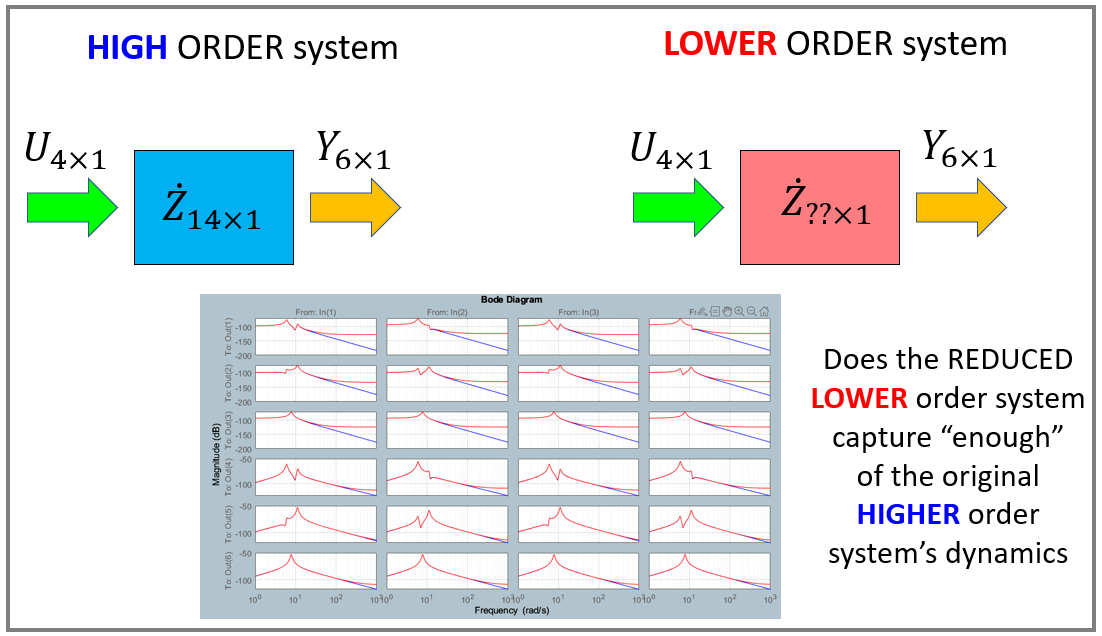

## Explore a Balanced Realization:

To explore which states are ***weakly coupled*** to the input and output, let's compute a Balanced Realization of our system using the  [`balreal()`](matlab:  web(fullfile(docroot, 'control/ref/lti.balreal.html'))) function.  The [`balreal()`](matlab:  web(fullfile(docroot, 'control/ref/lti.balreal.html'))) function:

- Will compute a co-ordinate transformation $\left(e\ldotp g\ldotp \bar{x} =T\ldotp x\right)$ for the state vector AND apply this to create a NEW system.   

- And it will also return the vector $\mathit{\mathbf{g}}$ corresponding to the diagonal of the transformed [control Grammian](https://en.wikipedia.org/wiki/Controllability_Gramian).  

- Small entries in $\mathit{\mathbf{g}}$ indicate states that could be removed to simplify the model

[sysb,g,T,Ti] = balreal(my_ss_MECH_sys);

Note the size of the balanced system:

fprintf(".... SIZE of BALANCED realization system:")
size(sysb)

Look at the $\mathit{\mathbf{g}}$vector

- Small entries in $\mathit{\mathbf{g}}$ indicate states that can be removed to simplify the model

figure;
    semilogy(g, '-ob', "LineWidth",2); grid('on');
    title(" g VALUES")

 So it looks like the first 6 states of the balanced system have the strongest coupling to the input and output.  

## Model Reduction

So let's reduce our system down to just these 6 dominant states.  And use the [`modred()`](matlab:  web(fullfile(docroot, 'control/ref/ss.modred.html'))) function to simplify(reduce) the system:

rsys     = modred(sysb, g<1e-3);

What's the size of the reduced order system

fprintf(".... SIZE of reduced order system:")
size(rsys)

And is this reduced system really more "controllable" and "observable"

tmp_rank = rank(ctrb(rsys))
if(tmp_rank < size(rsys.A,1))
    fprintf(" .... NOT controllable ! - after MODRED");
end

tmp_rank = rank(obsv(rsys))
if(tmp_rank < size(rsys.A,1))
    fprintf(" .... NOT controllable ! - after MODRED");
end

### The REDUCED model:

Ok:  let's play with this REDUCED model

my_sys = rsys;

You can compare the BODE plots of the original system to the REDUCED system

-  ***WARNING:***  This system BODE plot will take about 1 minute to plot and "embed" into the live script. If you highlight the code inside the IF statement and *"evaluate selection in Command window"* ... it runs VERY quickly

if(false)
    figure;
        % RED is the REDUCED system
        tmp_h = bodeplot(my_ss_MECH_sys, '-b', my_sys, '-r', {0, 1000});  
                 
                setoptions(tmp_h,'PhaseVisible','off');
                grid("on");
end

## Design a Full State Feedback controller

Although we could use the [**Pole Placement**](matlab:  web(fullfile(docroot, 'control/getstart/pole-placement.html'))) technique to design our Control Law $\left(u=-K\ldotp x\right)$, e.g.:  using the [`place()`](matlab:  web(fullfile(docroot, 'control/ref/place.html'))) function.  

An alternate approach for computing the GAIN matrix $K$is to use an "Optimal Control" technique called the [**Linear Quadratic Regulator**](https://en.wikipedia.org/wiki/Linear%E2%80%93quadratic_regulator)** - **we will explore this LQR approach today.

- OK, so let's design a **Linear Quadratic Regulator **using MATLAB's  [`lqr()`](matlab:  web(fullfile(docroot, 'control/ref/lti.lqr.html'))) function to force our states to ZER0.  

For a continuous time system, the state-feedback law $\left(u=\;-K\ldotp x\right)$ minimizes the quadratic cost function:

- 
$$J\left(u\right)=\int_0^{\infty } x^T \ldotp Q\ldotp x\;\;\;\;+\;\;\;\;u^T \ldotp R\ldotp u\;\;\;\;\;+\;\;\;\;\;2\ldotp x^T \ldotp N\ldotp u\;\;\;\mathrm{dt}$$


sz_T.Nz    = size(my_sys.A,1);
sz_T.Nu    = size(my_sys.B,2);
sz_T.Ny    = size(my_sys.C,1);

The $Q,R$ weighting matrices can be chosen using ***Bryson's rule***

- *A. E. Bryson, Jr. and Y. C. Ho, Applied Optimal Control. New York: Blaisdell, 1969*.

- 
$$Q_{\textrm{ii}} \;=\;\frac{1}{\textrm{MAX}\;\;\textrm{acceptable}\;\textrm{value}\;\textrm{of}\;x_i^2 }$$


- 
$$R_{\textrm{ii}} \;=\;\frac{1}{\textrm{MAX}\;\;\textrm{acceptable}\;\textrm{value}\;\textrm{of}\;u_i^2 }$$


But hand tuning is also fairly simple.  In General:

- Large $Q\Longrightarrow \;\;x$ should be made small within a short amount of time

- Small $R\Longrightarrow \;\;$  we will "spend" alot of $u$

Q          = 1e6; 
R          = 1; 
tmp        = ones(sz_T.Nz, sz_T.Nu);  
N          = tmp; 
[K,~,e]    = lqr(my_sys, Q, R, N)

#### What does the gain matrix K, look like?

  hfig = figure;
    heatmap(K,'Colormap', jet(50) );
        title("Controller GAIN matrix K")

 **ATTENTION:**  we will be using this $K$gain matrix in our Simulink simulation

## Design an OBSERVER

In order for the controller $u=-K\ldotp x$ to work, we'll need an **OBSERVER**(or estimator) to compute the full state vector $x$. 

-  A **Steady State**** Kalman filter(SSKF)** is a good place to start.  

Say we have a PLANT represented by $\left\lbrack A,B,C,D\right\rbrack$, with known inputs $u$ , **process noise** $w$ and **measurement noise** $v$.  The means of the process $w$ and measurement noise $y$ are ZERO  ... and their respective covariance matrices are $Q$ and $R$ respectively, i.e.:

- 
$$\dot{x} \;\;=\;A\ldotp x\;\;+\;\;\;B\ldotp u\;\;+\;\;G\ldotp w$$


- 
$$y\;\;=\;C\ldotp x\;\;+\;\;D\ldotp u\;\;+\;\;H\ldotp w\;\;+\;\;v$$
       

where:

- $E\left(w\right)=E\left(v\right)=0$   and   

- 
$$E\left({w\ldotp w}^T \right)=Q$$


- 
$$E\left({v\ldotp v}^T \right)=\;R$$


- 
$$E\left({w\ldotp v}^T \right)=N$$


The role of the **OBSERVER** is to take the signals $u\left(t\right)$ and $y\left(t\right)$ and to then compute an estimate of the FULL state vector $\hat{x} \left(t\right)$.  The design of an **SSKF observer** is done by the MATLAB function [`kalman()`](matlab:  web(fullfile(docroot, 'control/ref/ss.kalman.html')))`.`  

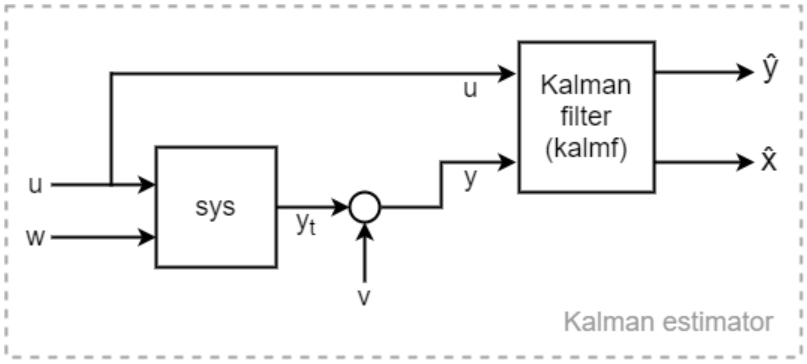

Internally, the **Steady State**** Kalman filter(SSKF)** is represented by the model

- 
$$\dot{\hat{x} } \;\;=\;A_{\textrm{PLANT}} \ldotp \hat{x} \;\;\;+\;\;B_{\textrm{PLANT}} \ldotp u\;\;+\;\;L\ldotp \left(y\;\;-C_{\textrm{PLANT}} \ldotp \hat{x} \;\;-D_{\textrm{PLANT}} \ldotp u\right)$$


 So ? - So the **SSKF** algorithm computes the GAIN matrix $L$

#### Augment the system with additional Process Noise inputs 

To use MATLAB's  [`kalman()`](matlab:  web(fullfile(docroot, 'control/ref/ss.kalman.html'))) function we need to convert our PLANT system into a NEW system where it has "additional" noise inputs, ie: In order to use the [`kalman()`](matlab:  web(fullfile(docroot, 'control/ref/ss.kalman.html'))) function, we'll construct an augmented system of the form:

- $\dot{x} \;\;=A\ldotp x\;\;+\;\;\left\lbrack B,\;G\right\rbrack \ldotp \left\lbrack \begin{array}{c}
u\\
w
\end{array}\right\rbrack$     and   $y\;\;=C\ldotp x\;\;+\;\;\left\lbrack D,H\right\rbrack \ldotp \left\lbrack \begin{array}{c}
u\\
w
\end{array}\right\rbrack$

sys_for_kalman = ss(   my_sys.A,                ...
                      [my_sys.B, eye(sz_T.Nz)], ...
                       my_sys.C,                 ...
                      [my_sys.D, zeros(sz_T.Ny, sz_T.Nz)], ...
                        'InputName',  cellstr([("u"+(1:sz_T.Nu)) ("w"+(1:sz_T.Nz))]), ...
                        'OutputName', cellstr( ("y"+(1:sz_T.Ny)) )   );

#### Specify the Covariance matrices for our Process and Measurement noise:

Q_noise_kal    = 1e6 * diag(ones(1, sz_T.Nz));
R_noise_kal    = 1   * diag(ones(1, sz_T.Ny));
N_kal          = 0   * ones(sz_T.Nz,sz_T.Ny);   

####  Now design the observer using the [`kalman()`](matlab:  web(fullfile(docroot, 'control/ref/ss.kalman.html'))) function:

[kalmf,L_kal,P_steady_state] = kalman(sys_for_kalman, Q_noise_kal, R_noise_kal, N_kal);

Our OBSERVER(i.e. the **SSKF**) is a state space system with the following INPUTS and OUTPUTS

- Observer INPUTS     = $\left\lbrack U_{\textrm{PLANT}} \;\;;Y_{\textrm{PLANT}} \right\rbrack$

- Observer OUTPUTS = $\left\lbrack {\hat{Y} }_{\textrm{PLANT}} \;\;;{\hat{X} }_{\textrm{PLANT}} \right\rbrack$

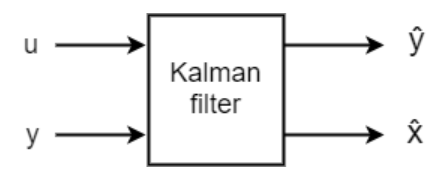

size(kalmf)

The  [`kalman()`](matlab:  web(fullfile(docroot, 'control/ref/ss.kalman.html'))) function also returns a gain matrix $L$.  So ? - So if you wanted to you could also implement the OBSERVER as:

- 
$$\dot{\hat{x} } \;\;=\;A_{\textrm{PLANT}} \ldotp \hat{x} \;\;\;+\;\;B_{\textrm{PLANT}} \ldotp u\;\;+\;\;L\ldotp \left(y\;\;-C_{\textrm{PLANT}} \ldotp \hat{x} \;\;-D_{\textrm{PLANT}} \ldotp u\right)$$


hfig = figure;
    heatmap(L_kal,'Colormap', jet(50) );
        title("Observer GAIN matrix L")

#### Now simulate the observer to determine it's capacity to estimate:

LOC_compare_plant_vs_observer(my_sys, kalmf, Q_noise_kal, R_noise_kal)

#### Final comments:

FYI:  Simulink also provides a [Kalman Filter BLOCK](matlab:  web(fullfile(docroot, 'control/ref/kalmanfilter.html'))).

 **ATTENTION:  **In our Simulink simulation we will in fact use the Simulink [Kalman Filter BLOCK](matlab:  web(fullfile(docroot, 'control/ref/kalmanfilter.html'))) rather than a state space block with `kalmf`

## Pause and Ponder

In the previous 2 sections we designed a Full State Feedback **Controller** AND an **OBSERVER**.  The plant that we used for these two design tasks was based on a Mechanical model where we "ignored" the ground displacement forces - and assumed that they were "disturbances".

 So ? - So when we run our SYSTEM level model we should expect that we'll need to TUNE either the control Law and/or the OBSERVER.

## Open the Simulink model

Now open and run the Simulink model to test the Control system:

open_system("bh_SIM_7dof_car_active_suspension")    

# **Local Subfunctions only beyond this point**

Create Simulink Blocks

function LOC_create_SL_blocks(M_mat, C_mat, K_mat, F_col)

    MODEL_NAME = 'bh_tmp_model_WILL_BE_DELETED';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    purple_str = '[0.6, 0.6, 1]';
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/my_M_mat'], M_mat);
    matlabFunctionBlock( [MODEL_NAME,'/my_C_mat'], C_mat);    
    matlabFunctionBlock( [MODEL_NAME,'/my_K_mat'], K_mat);   
    matlabFunctionBlock( [MODEL_NAME,'/my_F_col'], F_col);
    
    % make the blocks a YELLOW color
    set_param([MODEL_NAME,'/my_M_mat'],'BackgroundColor',purple_str,'Position', [-325   262  -190   478]);
    set_param([MODEL_NAME,'/my_C_mat'],'BackgroundColor',purple_str,'Position', [45   -46   180   271]);    
    set_param([MODEL_NAME,'/my_K_mat'],'BackgroundColor',purple_str,'Position', [45   308   180   617]);
    set_param([MODEL_NAME,'/my_F_col'],'BackgroundColor',purple_str,'Position', [610     2   735   563]);    

end

Replace the symbolic symbols with NUMERIC values

function [M,C,K] = LOC_get_MCK(M_sym, C_sym, K_sym, OBJ_car_params)

    syms L_b  L_f    L_R   L_L
    syms  m_c    I_cZ    I_cX
    syms  m_bR   m_fR    m_bL    m_fL
    syms  k_bR   k_fR    k_bL    k_fL
    syms  c_bR   c_fR    c_bL    c_fL
    syms  k_bRG  k_fRG   k_bLG   k_fLG
    syms  c_bRG  c_fRG   c_bLG   c_fLG
    
    the_sym_list = [ L_b,    L_f,     L_R,     L_L,   ...
                     m_c,    I_cZ,    I_cX,           ... 
                     m_bR,   m_fR,    m_bL,    m_fL,  ...
                     k_bR,   k_fR,    k_bL,    k_fL,  ...
                     c_bR,   c_fR,    c_bL,    c_fL,  ...
                     k_bRG,  k_fRG,   k_bLG,   k_fLG, ...
                     c_bRG,  c_fRG,   c_bLG,   c_fLG      ];
    
    the_value_list = zeros(size(the_sym_list));
    
    for kk=1:length(the_sym_list)
        NAME                = string(  the_sym_list(kk)  );
        the_value_list(kk)  = OBJ_car_params.car_tab{NAME, "Value"};
    end
    
    M = subs(M_sym, the_sym_list, the_value_list);
    C = subs(C_sym, the_sym_list, the_value_list);
    K = subs(K_sym, the_sym_list, the_value_list);  
    
    M = double(M);
    C = double(C);
    K = double(K);

end

Compare Plant against OBSERVER

function LOC_compare_plant_vs_observer(my_plant, my_kal, Q_noise_kal, R_noise_kal)
    
    rng(0);
    
    t_col   = [0:0.01:10]';
    N       = length(t_col); 
    u_known = 5000*sin(2*pi*t_col*[0.5, 1, 1.5, 2]);
    
    plant_2 = ss(my_plant.A, my_plant.B,  eye(size(my_plant.A,1)), zeros(size(my_plant.A,1),  size(my_plant.B,2)) );
    
    y_plant = lsim(my_plant,  u_known,  t_col);
    x_plant = lsim(plant_2,   u_known,  t_col);
    
    v_noise = randn(length(t_col), size(R_noise_kal,1));
    
    var_row = diag(R_noise_kal)';
    std_row = sqrt(var_row);
    v_noise = v_noise .* repmat(std_row, length(t_col), 1);
    
    yV_plant=y_plant + v_noise;
    %yV_plant=y_plant ;
    
    ye_xe   = lsim(my_kal, [u_known,yV_plant],t_col);    
    ye      = ye_xe(:,  1:size(my_plant.C,1));    
    xe      = ye_xe(:,  ((end-(size(my_plant.A,1)-1)):end));
        
    assert(size(xe,2)==size(my_plant.A,1), "###_ERR:  why did this happen ?")
       
    Ns = size(my_plant.A,1);
    
    for kk=1:Ns
        figure;
          plot(t_col, x_plant(:,kk), '-b', 'LineWidth',2);
          hold on
          plot(t_col,      xe(:,kk), '-r.');
          grid("on");  
          xlabel('t (secs)');
          legend(["TRUE x","EST x"])   
          title("State #"+kk);
    end

    Ny = size(my_plant.C,1);   
    for kk=1:Ny
        figure;
          plot(t_col, y_plant(:,kk), '-k', 'LineWidth',2);
          hold on
          plot(t_col,      ye(:,kk), '-m.');
          grid("on");  
          xlabel('t (secs)');
          legend(["TRUE y","EST y"])   
          title("OUTPUT #"+kk);
    end    
    
end

Compare the ORIGINAL **Mechanical plant** against the OBSERVER

% function LOC_compare_MECH_vs_observer(my_plant, my_kal, Q_noise_kal, R_noise_kal)
%     
%     rng(0);
%     
%     t_col   = [0:0.01:10]';
%     N       = length(t_col); 
%     u_known = 5000*sin(2*pi*t_col*[0.5, 1, 1.5, 2]);
%        
%     y_plant = lsim(my_plant,  u_known,  t_col);
%     
%     v_noise = randn(length(t_col), size(R_noise_kal,1));    
%     var_row = diag(R_noise_kal)';
%     std_row = sqrt(var_row);
%     v_noise = v_noise .* repmat(std_row, length(t_col), 1);
%     
%     yV_plant=y_plant + v_noise;
%     %yV_plant=y_plant ;
%     
%     ye_xe   = lsim(my_kal, [u_known,yV_plant],t_col);
%     
%     ye      = ye_xe(:,  1:size(my_plant.C,1));
%     %xe      = ye_xe(:,  ((end-(size(my_plant.A,1)-1)):end));
%     
%     Ny = size(my_plant.C,1);
%     
%     for kk=1:Ny
%         figure;
%           plot(t_col, y_plant(:,kk), '-k', 'LineWidth',2);
%           hold on
%           plot(t_col,      ye(:,kk), '-m.');
%           grid("on");  
%           xlabel('t (secs)');
%           legend(["TRUE y","EST y"])   
%           title("OUTPUT #"+kk);
%     end
% 
% end